Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\bonar\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "EEGLab-Plugin-master" v1.1 (see >> help eegplugin_NE)
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.02' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu


ERPLAB WARNING: Temporary files (from your last session) within erplab_Box folder were sent to recycle bin.

EEGLAB: adding "ERPLAB" v10.02 (see >> help eegplugin_erplab) - new version 10.04 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel) - n

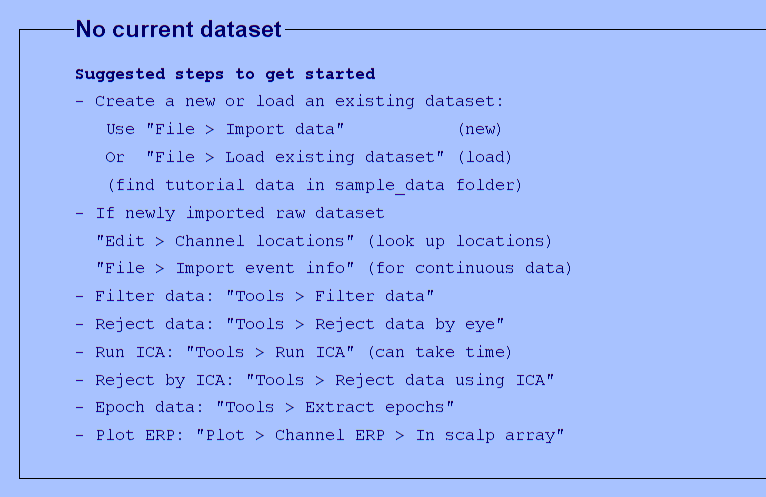

%pathtool; % Set current folder
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab; % Open EEGLAB

## Plugins Needed

Have these in the current folder already:

- clean_rawdata

- dipit

- ERPLAB10.02

- firfilt

- ICLabel

- SIFT

- xdfimport1.18

## Before running code, be on UCB VPN

## 1. PREPARING THE DATA SET

% Populate raw xdf file
    filepath = 'C:\Users\Iris Li\Desktop\iris_data\sub-N002_ses-S001_task-Default_run-001_eeg.xdf'; % INPUT location of xdf file
    EEG = pop_loadxdf(filepath, 'streamtype', 'EEG', 'exclude_markerstreams', {});

Now importing...

Error using load_xdf
The file "C:\Users\Iris Li\Desktop\iris_data\sub-N002_ses-S001_task-Default_run-001_eeg.xdf" does not exist.

Error in eeg_load_xdf (line 35)
streams = load_xdf(filename);

Error in pop_loadxdf (lin

    filename1 = 'raw'; % change file name if desired
    [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'setname', filename1,'gui','off'); 

% Read default 32 easy channel locations into the xdf file using dipfit
    eeglabpath = '.\..\'; % INPUT location of eeglab
    dipfitpath = strcat(eeglabpath,'\eeglab2023.1\plugins\dipfit\standard_BEM\elec\standard_1005.elc');
    defaultchans = 'Z:\files\MATRIKS\lbonarrigo\EEGLAB_Pipeline_Loc_Files\32_chan_locs'; % in Shuttle server
    EEG=pop_chanedit(EEG, 'lookup', dipfitpath, 'load',{defaultchans,'filetype','loc'});
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

% remove 12 channels, keep channels 1-20
    EEG = pop_select( EEG, 'channel',{'P7','P4','Cz','Pz','P3','P8','O1','O2','T8','F8','C4','F4','Fp2','Fz','C3','F3','Fp1','T7','F7','Oz'});
    filename2 = 'raw_20chan';
    [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'setname',filename2,'gui','off'); 

% read in 20-channel easy locations file and update blank labels using dipfit
    twentychans = 'Z:\files\MATRIKS\lbonarrigo\EEGLAB_Pipeline_Loc_Files\20_chan_EasyLoc.com'; % in Shuttle server
    EEG=pop_chanedit(EEG, 'load',{twentychans,'filetype','loc'},'changefield',{9,'labels','PO7'},'changefield',{11,'labels','O9'},'changefield',{15,'labels','Iz'},'changefield',{18,'labels','O10'},'changefield',{20,'labels','PO8'},'lookup', dipfitpath);
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

% export events and find condition timespan range
% TO DO: REPLACE THIS SECTION WITH NEW CODE THAT FINDS THE START AND END TIMES OF CONDITION
% pop_expevents(EEG, 'C:\Users\Iris Li\Desktop\NEWOBACKIRIS.txt', 'samples');

% Select time window of condition to analyze via this pipeline
    timespan = [32 96];
    EEG = pop_select( EEG, 'time', timespan);
    filename3 = 'raw_0back'; % input condition name
    [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 2,'setname', filename3,'gui','off'); 

## 2. FILTER OUT ARTIFACTS

1. FIR Filter

maxfreq = 40; % noise above this frequency filters out (Hz)
minfreq = 1; % noise below this frequency filters out (Hz)
EEG = pop_eegfiltnew(EEG, 'locutoff', minfreq, 'hicutoff', maxfreq);
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 3,'setname','filt1','gui','off'); 

2. Clean Rawdata and ASR

EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',4,'Highpass','off','BurstCriterion',20,'WindowCriterion',0.25,'BurstRejection','on','Distance','Euclidian','WindowCriterionTolerances',[-Inf 7] );
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 4,'setname','filt2','gui','off'); 

3. ICA decomposition

EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
EEG = pop_iclabel(EEG, 'default');
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
% Open each IC:
% TO DO: disable these pop-ups and add code that
% inputs range into otherrange based on the percentage thresholds
% of "Other" components we desire to remove.
% [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 6,'retrieve',1,'study',0); 
% [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'retrieve',2,'study',0);

% Select range for flagging component for rejection
otherrange = [0.6 1]; % change this range accordingly
EEG = pop_icflag(EEG, [NaN NaN;NaN NaN;NaN NaN;NaN NaN;NaN NaN;NaN NaN;otherrange]);
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

% Removal of [] flagged components
EEG = pop_subcomp( EEG, [], 0);
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 5,'gui','off');


## Generate plot of channel spectra and maps

hold on;
figure; 
hold off;
pop_spectopo(EEG, 1, [0      26986.0715], 'EEG' , 'freq', [3 6 11 20 30], 'freqrange',[1 40],'electrodes','off');
figurefile = sprintf('%s_%s.jpg', 'condition', 'subject'); %fill in condition and subject
saveas(gcf, fullfile('C:\Users\Iris Li\Desktop', figurefile));

eeglab redraw;